Source code for "**Coupling of vegetation structure and physiology explains global greenness dynamics"** 

To understand the emergent seasonal pattern of vegetation greenness based on the concept of optimality, we hypothesized that the seasonal dynamics of canopy greenness tracks that of canopy potential production. Canopy greenness was indexed by fraction of absorbed photosynthetically active radiation (fAPAR). Canopy potential production was defined here as the rate of canopy photosynthesis that would be achieved if all light were absorbed by green tissues (A0), which was estimated from climate variables with a universal photosynthesis model, the P model. We tested our hypothesis at a global scale by comparing the spatial patterns of fAPAR seasonality and A0 seasonality, especially their corelation coefficient cross grid cells and along the latitudinal gradient. We also tested our hypothesis at flux sites cross various biomes with corelation coefficient of observed monthly fAPAR and the P model predicted monthly A0. With the extensive supports from satellite data and ground data, we further developed a universal model of canopy greenness (the PL model) in which the seasonal dynamics of fAPAR are predicted directly from the climate-driven seasonal cycle of A0. We evaluated our PL model by comparing the fAPAR predictions with the remote sensing data, and predictions from state-of-the-art process-based models in TRENDY projects. We also applied the PL model to predict historical trends in global fAPAR and GPP with a comparison with TRENDY models, and identify the primary drivers of global greening and browning trends with a factorial simulation.

**Fig.1 | Seasonality of the fraction of absorbed photosynthetically active radiation (*****f*****APAR, dimensionless) and potential primary production (*****A*****0, g C m−2 month−1)**. (**a)** *f*APARseasonality derived from the MODIS product. (**b**) *A*0 seasonality derived from the P model. (**c**) Latitudinal variations in the seasonality of *f*APAR and *A*0, with values representing area-weighted averages in 1° latitudinal bands.

roi_single_year = geotiffread("../data/roi_global_05d.tif"); %#ok<*GTRED> 

addpath("./utility/");
timestep = 30;
font_size = 11;
options.fontsize = 14;
options.text_position_middle = [-56,-46];
options.text_position_right = [-158,-46];
fapar_obs_mon = geotiffread("../data/fapar_global_modis_05d.tif");
fapar_sim_mon = geotiffread("../data/fapar_global_plmodel_05d.tif");
raster_trendy_12mon = geotiffread("../data/fapar_trendy_plmodel_05d.tif");
A0_gC_weekly = geotiffread("../data/a0_global_plmodel_05d.tif");

[seasonalityA0,timingA0,timingA0Cos] = TS(A0_gC_weekly,'timestep',timestep);
[seasonalityPL,timingPL,timingPLCos] = TS(fapar_sim_mon,'timestep',timestep);

[seasonalityMod,timingMod,timingModCos] = TS(fapar_obs_mon,'timestep',timestep);

[seasonalityTrendy,timingTrendy,timingTrendyCos] = TS(raster_trendy_12mon,'timestep',timestep);

% show the data
cb_paired = cbrewer_hint("qual", "Paired", 12);
cb_set1 = cbrewer_hint("qual","Set1",9);
cb_set2 = cbrewer_hint("qual","Set2",8);
cb_pastel2 = cbrewer_hint('qual','Pastel2',9);

YearBgn = 2000;
YearEnd = 2019;
YearNum = numel(YearBgn:YearEnd);

options.range_value = [0, 0.9];
options.text_position = [-160,-45];
roi_12mon = repmat(roi_single_year, [1,1,12]);

path_figure_output = '../figure/';

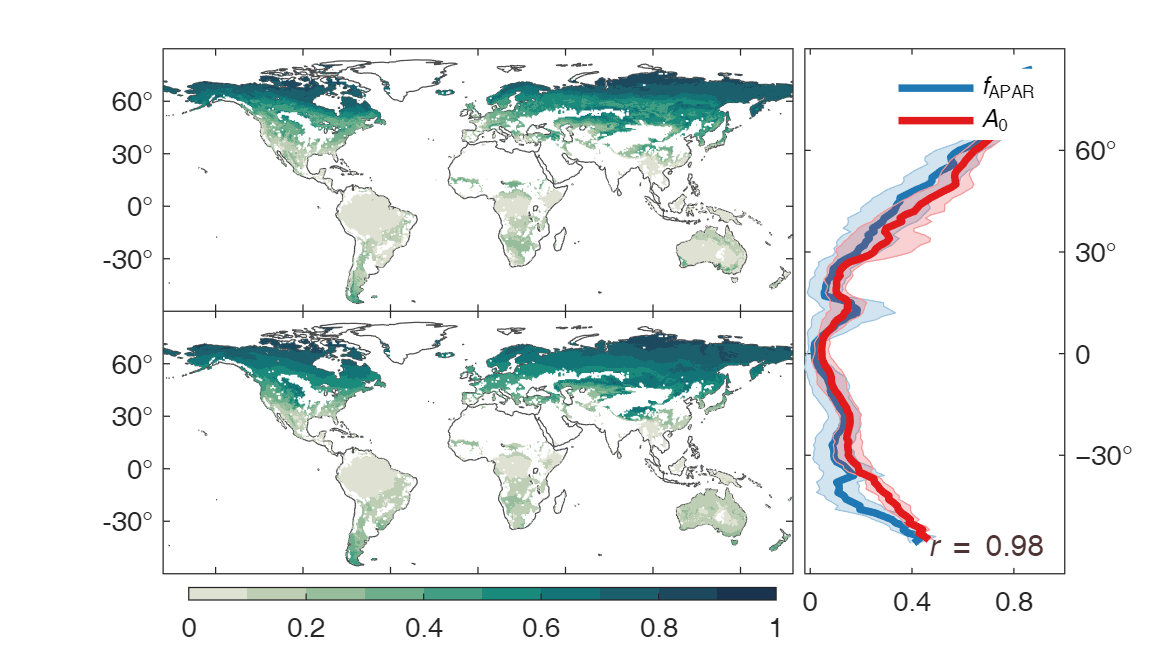

fig = figure('Color', [1 1 1]);
% the width of the data
fig.Position(3) = fig.Position(3)*1.12;
% the height of the data
fig.Position(2) = fig.Position(2)*0.6;
fig.Position(4) = fig.Position(4)*0.82;

% tiledlayout("Vertical","Padding","compact");
left_width = 10;
right_width = 4;
tiledlayout(2,left_width + right_width,"TileSpacing","tight");

nexttile(1, [1,left_width]);
data_obs = seasonalityMod;
data_obs(~(roi_single_year)) = nan;
geoshow_global(data_obs,"logic_show_yticks","true","logic_show_xticks","false");
set(gca, 'Clim', [0, 1.0])
% title(['\it{f}\rm_{APAR} ', 'Seasonality'])
% text(xtext, ytext, ['\it{f}\rm_{APAR} ', 'Seasonality'],'FontSize',options.fontsize-2)
set(gca,'FontSize',options.fontsize-3)
% grid on

nexttile(1+(left_width+right_width), [1,left_width]);
data_sim = seasonalityA0;
data_sim(~(roi_single_year)) = nan;
geoshow_global(data_sim,"logic_show_yticks","true","logic_show_xticks","false");
set(gca, 'Clim', [0, 1])
% title(['\it{A}\rm_{0}\rm ', 'Seasonality'])
set(gca,'FontSize',options.fontsize-3)
% text(xtext, ytext, ['\it{A}\rm_{0}\rm ', 'Seasonality'],'FontSize',options.fontsize-2)
% grid on;

% cb_map = slanCM(53, 12); colormap(cb_map(2:(end-1),:));
cb_map = slanCM(56, 12); colormap(cb_map(2:(end-1),:));

% colormap(flipud(cb_gnbu));
% font_size = 11;
cb = colorbar(gca, 'southoutside','FontSize',font_size, 'Position', [0.16, 0.07, 0.50, 0.02]);% cbarrow
% cb.Position(4) = cb.Position(4)*0.6;

nexttile(1+left_width, [2,right_width])
if(true)
    plot_lat_bands(cat(3,data_obs,data_sim), "logic_plot",true, "ylabel",'','fontsize',12,'fontbold','normal','str_legend',["\it{f}\rm_{APAR}","\it{A}\rm_{0}\rm"],'line_color',cb_paired([2,6],:));
    set(gca,'FontSize',options.fontsize-3)
    yticks(0:0.4:1)
    % grid on;
end
% export data
exportgraphics(gcf, fullfile(path_figure_output, 'Seasonality_Pattern_A0.png'),"Resolution",600);

**Fig | Relationship between greenness (*****f*****APAR, determining canopy light absorption) and the seasonal dynamics of potential productivity (*****A*****0) at site level. **

% show the spatial pattern
param_table = readtable("../data/FluxInformation.csv");

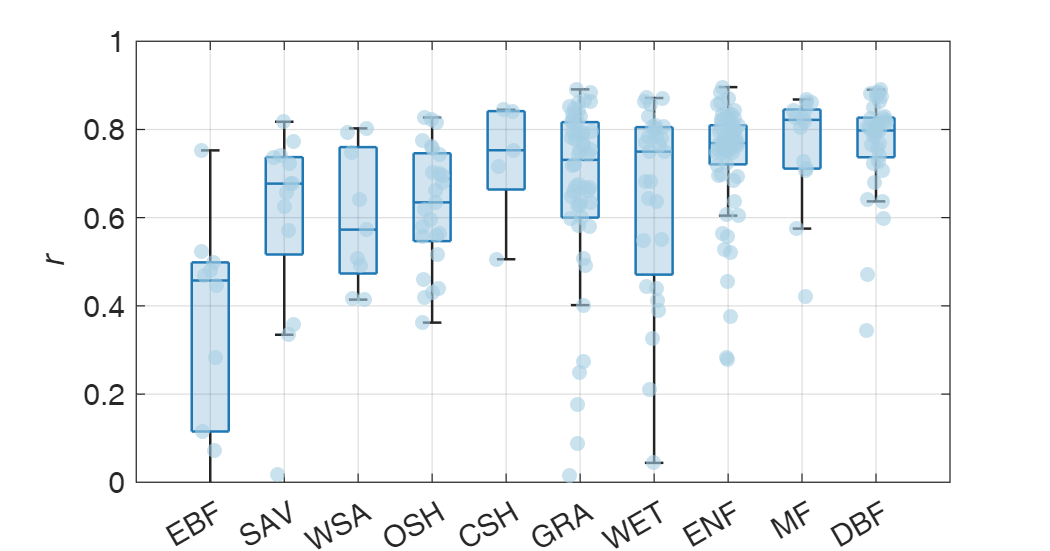

fig = figure;
fig.Position(4) = fig.Position(4)*0.7;
colororder(fig, cb_paired([2,1,6],:))

% sequence of the data
param_table_target = ["EBF","SAV","WSA","OSH","CSH","GRA","WET","ENF","MF","DBF"];
param_table.categorial = categorical(param_table.IGBPClass, param_table_target, param_table_target);

% Pmodel vs. Flux
nexttile;
hold on
index_grp = cat(1, repmat(categorical("P model"), height(param_table),1));
boxchart(repmat(param_table.categorial, [1,1]), [param_table.r_a0_fapar], 'GroupByColor',index_grp,"MarkerStyle","none","Notch","off","MarkerSize",12,"JitterOutliers","off");
ylabel('\it{r}','FontSize',options.fontsize)
ylim([0,1])
set(gca, 'fontsize', options.fontsize-2)

[found, idx] = ismember(param_table.categorial, categorical(param_table_target));
if any(~found)
   error('Site not on approved list, first at row %d', find(~found,1));
end
[~, sortorder] = sort(idx);
newT = param_table.categorial(sortorder,:);

% [C, ~, ic]= unique([param_table.categorial],'stable');
% scatter(ic,param_table.r_a0_fapar,'filled','MarkerFaceAlpha',0.6','jitter','on','jitterAmount',0.15);
scatter(newT,param_table.r_a0_fapar(sortorder,:),'filled','MarkerFaceAlpha',0.6','jitter','on','jitterAmount',0.15);
   
hold off
box on
grid on

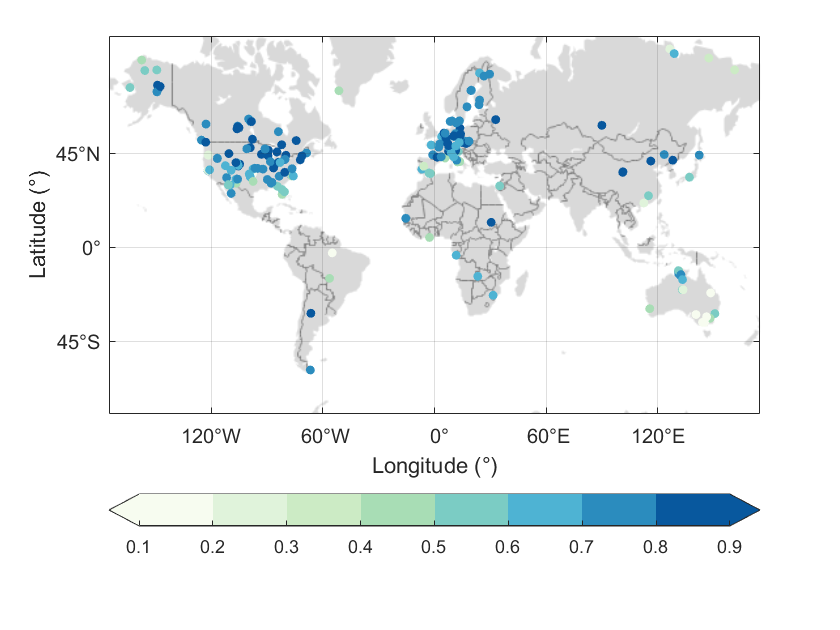

figure;
ax = geoaxes();
ax.Scalebar.Visible = 'off';
% flux tower derived correlation
geoscatter(double(param_table.Lat), double(param_table.Lon), 20, param_table.('r_a0_fapar'),"filled");

% pmodel derived correlation
% geoscatter(double(param_table.lat), double(param_table.lon), 20, param_table.('r_a0_fapar_snu'),"filled");

ax.LongitudeLabel.String = 'Longitude (°)';
ax.LatitudeLabel.String = 'Latitude (°)';
% ax.LatitudeLimits = [-60, 80]; % read only
% ax.LongitudeLimits = [-175, 175];
geolimits(ax,[-60, 70],[-175, 175]);

cb = colorbar('Location','southoutside');
% cb.Position(4) = cb.Position(4)*0.4;
% title(cb, 'r');
cb_spectral = cbrewer_hint('div', 'Spectral', 10);
% colormap(cb_spectral(2:9,:))
% colormap(flipud(slanCM(61, 8)))
% colormap(cbrewer_hint("div","RdBu",8))
colormap(cbrewer_hint("seq","GnBu",8))

set(gca, 'Clim', [0.1,0.9])
warning off;
cbarrow;
warning on;
geobasemap("grayland")

**Fig | Comparison of the spatial distribution of monthly *****f*****APAR****from remote sensing with PL model predictions**. (**a**) Scatter plot of multi-year monthly *f*APAR for each 0.5°grid cell from 2001 to 2019. The red line is the linear fit; the grey line is the 1:1 line. Colours represents the density of points. Global distributions of multi-year average monthly *f*APAR from (**b**) the PL model and (**c**) the MODIS product.

% show the spatial pattern
fig = figure('Color', [1 1 1]);
fig.Position(3) = fig.Position(3)*1.3;
tiledlayout(2,3,"TileSpacing","compact")
nexttile(1, [1,2]);
fapar_predicted_min_matrix_disp = mean(fapar_sim_mon, 3, "omitnan");
fapar_predicted_min_matrix_disp(~roi_single_year) = nan;
geoshow_global(fapar_predicted_min_matrix_disp,"logic_show_yticks","true","logic_show_xticks","false");
% colorbar;
set(gca, 'Clim', options.range_value)
text(options.text_position_middle(1)+34, options.text_position_middle(2)-2, 'PL model','FontSize',options.fontsize)
set(gca,'FontSize',options.fontsize-0)
% grid on

nexttile(4, [1,2]);
data_disp = mean(fapar_obs_mon, 3, "omitnan");
data_disp(data_disp==0)=nan;
data_disp(~roi_single_year) = nan;
geoshow_global(data_disp,"logic_show_yticks","true","logic_show_xticks","false")
set(gca, 'Clim', options.range_value)

cb = colorbar(gca, 'southoutside','FontSize',font_size, 'Position', [0.14, 0.07, 0.48, 0.02]);% cbarrow
cbarrow('right');

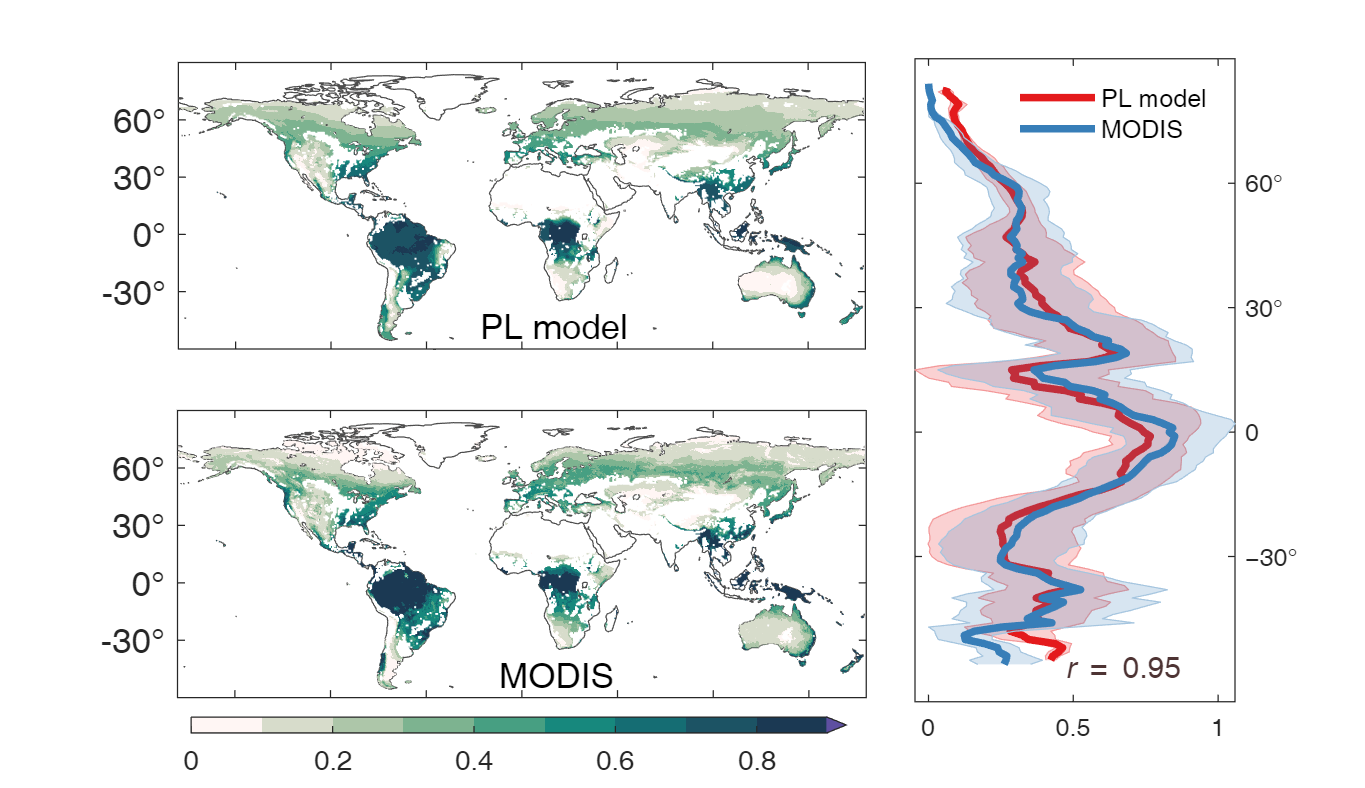

text(options.text_position_middle(1)+44, options.text_position_middle(2)-2, 'MODIS','FontSize',options.fontsize)
set(gca,'FontSize',options.fontsize-0)
% grid on;

% colormap(cbrewer_hint("seq","GnBu",9));
cb_map = slanCM(56, 10); colormap(cb_map(1:(end-1),:));

nexttile(3, [2,1])
if(true)
    plot_lat_bands(cat(3,fapar_predicted_min_matrix_disp, data_disp), "logic_plot",true, "ylabel",'','fontsize',12,'fontbold','normal','str_legend',["PL model","MODIS"],'line_color',cb_set1(1:4,:));
    % grid on;
end
% export figure
exportgraphics(gcf, fullfile(path_figure_output, 'spatial_compare.png'),"Resolution",600);

Pixel by Pixel comparison

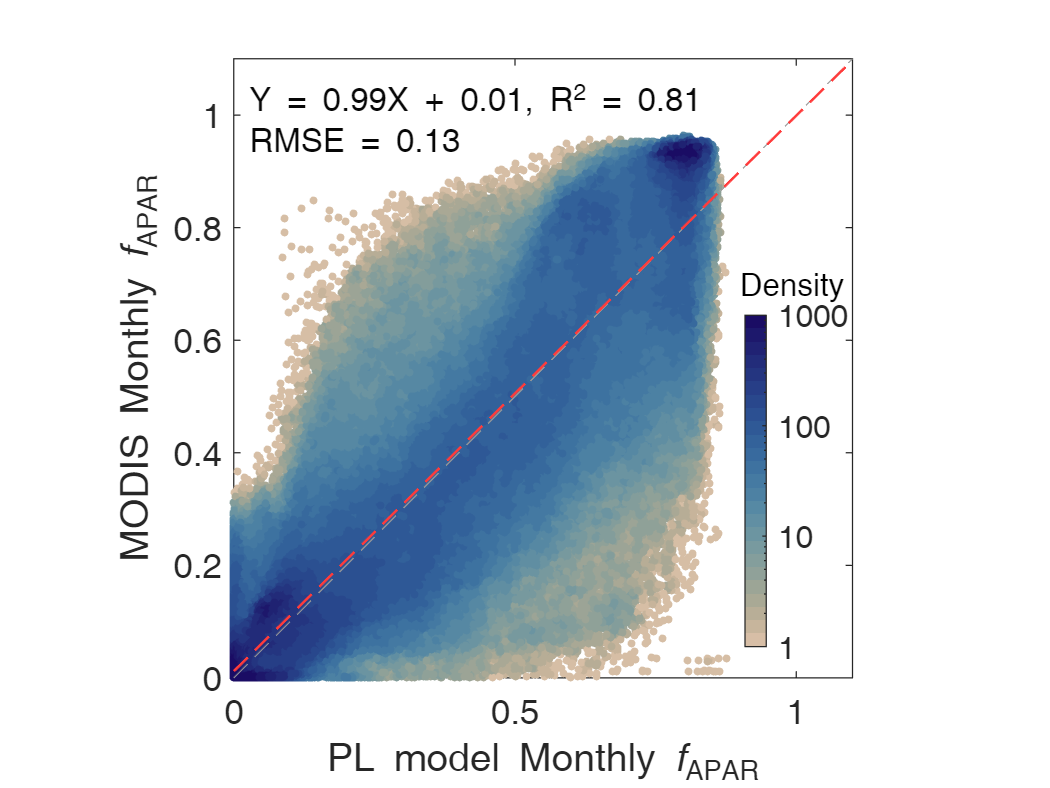

figure;
% xData = mean(fapar_weekly,3,'omitnan');
% yData = pmodel.cal_fapar(mean(TLAI15DE1,3,'omitnan'));
% scatter_plot_data_comparison(yData(ROI_SINGLE), xData(ROI_SINGLE),"PlotDisp","off","PlotDensity","on","PlotConf","off","AxisLim",[0,1,0,1],"AxisEqual","on","StatisLocation","southeast","StatisDispItem","r2+rmse+equ","StatisCrossZero","on");
set(gca,'fontsize',13)

scale_factor = 1;
method_function = 'nanmean';
% method_function = 'max';
fapar_sim_resample = fapar_sim_mon;
fapar_obs_resample = fapar_obs_mon;
roi_resample = roi_12mon;
roi_resample = logical(roi_resample);
% switch 'a0'

% Satellite data
scatter_plot_data_comparison(fapar_sim_mon(roi_resample), fapar_obs_mon(roi_resample), "PlotDisp","off","PlotDensity","on","PlotConf","off","AxisLim",[0,1.1,0,1.1],"AxisEqual","on","StatisLocation","northwest","StatisDispItem","r2+rmse+equ","StatisCrossZero","off", "RobustOpts","off","FontSize",options.fontsize-2);
% scatter_plot_data_comparison(fapar_sim_mon(roi_resample), pmodel.cal_fapar(data_12months_pu(roi_resample)), "PlotDisp","off","PlotDensity","on","PlotConf","off","AxisLim",[0,1.1,0,1.1],"AxisEqual","on","StatisLocation","northwest","StatisDispItem","r2+rmse+equ","StatisCrossZero","off");
% Trendy models
% scatter_plot_data_comparison(raster_trendy_12mon(roi_resample), fapar_obs_mon(roi_resample), "PlotDisp","off","PlotDensity","on","PlotConf","off","AxisLim",[0,1.1,0,1.1],"AxisEqual","on","StatisLocation","northwest","StatisDispItem","r2+rmse+equ","StatisCrossZero","off");
xlabel('PL model Monthly \it{f}\rm_{APAR}')
ylabel('MODIS Monthly \it{f}\rm_{APAR}')
% axis([0,1,0,1])
% axis equal
grid off
% Set the log colobar
set(gca,'ColorScale','log')
set(gca,'fontsize',options.fontsize)
text(0.9, 0.7, "Density","FontSize",options.fontsize-1.5)
cb = colorbar(gca, 'eastoutside','Units','normalized');
cb.Position = [0.71, 0.18, 0.02, 0.42];
cb.Ticks = [10^-2, 10^-1, 1, 10];
set(gca, 'clim', [cb.Ticks(1), cb.Ticks(end)])

% cbarrow('up');
% cb.Limits = [cb.Ticks(1), cb.Ticks(end)];
% cb.Label('Density')
cb.TickLabels = {'1', '10', '100', '1000'};
% cb_color = cbrewer_hint("div","PRGn",30); cb_color = flipud(cb_color); colormap(cb_color(4:26,:));
% cb_color = cbrewer_hint("seq","YlGnBu",30); colormap(flipud(cb_color(1:23,:)));
% cb_greys = cbrewer_hint('seq', "Greys", 5);
% cb_blues = cbrewer_hint('seq', 'Blues', 10);

% cb_color = cbrewer_hint("div","RdBu",30); cb_color = flipud(cb_color); colormap(cb_color(4:28,:));
% cb_color = cbrewer_hint("seq","Blues",30); cb_color = flipud(cb_color); colormap(cb_color(4:30,:));
% cb_map = slanCM(46, 30); cb_map = flipud(cb_map); colormap(cb_map(4:(end),:));
cb_map = slanCM(1, 30); colormap(cb_map(6:(end-2),:)); % classic color viridis
cb_map = slanCM(61, 30); cb_map = flipud(cb_map(1:(end-5),:)); colormap(cb_map); % classic color viridis

**Fig | Comparison of the seasonal dynamics of MODIS *****f*****APAR****with predictions from the PL and TRENDY models. **Global distribution of *f*APARseasonality derived from the (**a**) the MODIS product, (**b**) the TRENDY ensemble of models and (**c**) the PL model. (**d**) *R*2 and Root Mean Square Error, RMSE statistics for the comparison of modelled and observed monthly *f*APAR. Model details are provided in Supplementary Table 1. 

% Input Parameter: Vector(12x1) or Matrix(n*m*12)
timestep = 30;

ct_left = cbrewer_hint("div","RdYlBu",8);
ct_right = flipud(cbrewer_hint("div","RdYlBu",6));

% write data to files
% geotiffwrite("Seasonality A0.tif", seasonalityA0, R);
% geotiffwrite("Seasonality MODIS.tif", seasonalityMod, R);

% Seasonality
model_name = 'Pmodel';

xtext = -56;
ytext = -44;
sizetext = 12;

fig = figure('Color', [1 1 1]);
% the width of the data
fig.Position(3) = fig.Position(3)*0.7;
% the height of the data
fig.Position(2) = fig.Position(2)*0.6;
fig.Position(4) = fig.Position(4)*1.2;

% tiledlayout("Vertical","Padding","compact");
tiledlayout(3,1,"TileSpacing","tight");

% nexttile(1, [1,1]);
% data_sim = seasonalityA0;
% data_sim(~(roi_single_year)) = nan;
% geoshow_global(data_sim,"logic_show_ticks","true");
% set(gca, 'Clim', [0, 1])
% title(['\it{A}\rm_{0}\rm ', 'Seasonality'])
% text(xtext, ytext, ['\it{A}\rm_{0}\rm ', 'Seasonality'],'FontSize',sizetext)

nexttile(2, [1,1]);
data_obs = seasonalityMod;
data_obs(~(roi_single_year)) = nan;
geoshow_global(data_obs,"logic_show_ticks","false");
set(gca, 'Clim', [0, 1.0])
% title(['\it{f}\rm_{APAR} ', 'Seasonality'])
text(xtext, ytext, ['\it{f}\rm_{APAR} ', 'Seasonality'],'FontSize',sizetext)
set(gca,'FontSize',options.fontsize)
% grid on;

nexttile(3, [1,1]);
data_sim = seasonalityPL;
data_sim(~(roi_single_year)) = nan;
geoshow_global(data_sim,"logic_show_ticks","false");
set(gca, 'Clim', [0, 1])
text(xtext, ytext, ['PL model ', 'Seasonality'],'FontSize',sizetext)
set(gca,'FontSize',options.fontsize)
% grid on;
% nexttile(4, [1,1]);
% data_sim = seasonalityISBA;
% data_sim(~(roi_single_year)) = nan;
% geoshow_global(data_sim,"logic_show_ticks","false");
% set(gca, 'Clim', [0, 1])

nexttile(1, [1,1]);
data_sim = seasonalityTrendy;
data_sim(~(roi_single_year)) = nan;
geoshow_global(data_sim,"logic_show_ticks","false");
set(gca, 'Clim', [0, 1])
text(xtext, ytext, ['TRENDY ', 'Seasonality'],'FontSize',sizetext)
set(gca,'FontSize',options.fontsize)
% grid on;
% colormap(slanCM('Seasons', 12))
% cb_gnbu = cbrewer_hint("div","Spectral",15);
% colormap(flipud(cb_gnbu(5:14,:)));

% cb_gnbu = cbrewer_hint("div","RdYlBu",10);
% cb_gnbu = cbrewer_hint("seq","PuBuGn",10);
% cb_map = slanCM(53, 12); colormap(cb_map(2:(end-1),:));
cb_map = slanCM(56, 12); colormap(cb_map(2:(end-1),:));
% colormap(flipud(cb_gnbu));
font_size = 11;

cb = colorbar(nexttile(3), 'southoutside','FontSize',font_size);% cbarrow
cb.Position(4) = cb.Position(4)*0.4;

cbarrow('right')

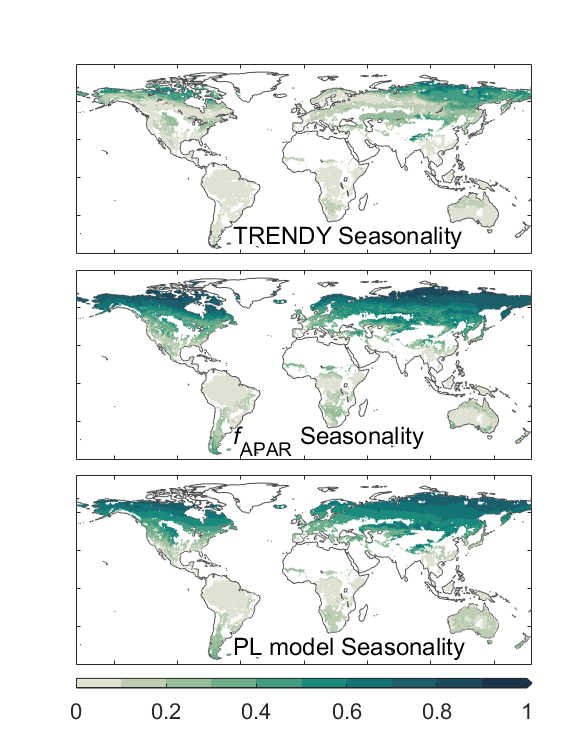

exportgraphics(gcf, fullfile(path_figure_output, 'Seasonality_Pattern.png'),"Resolution",600);

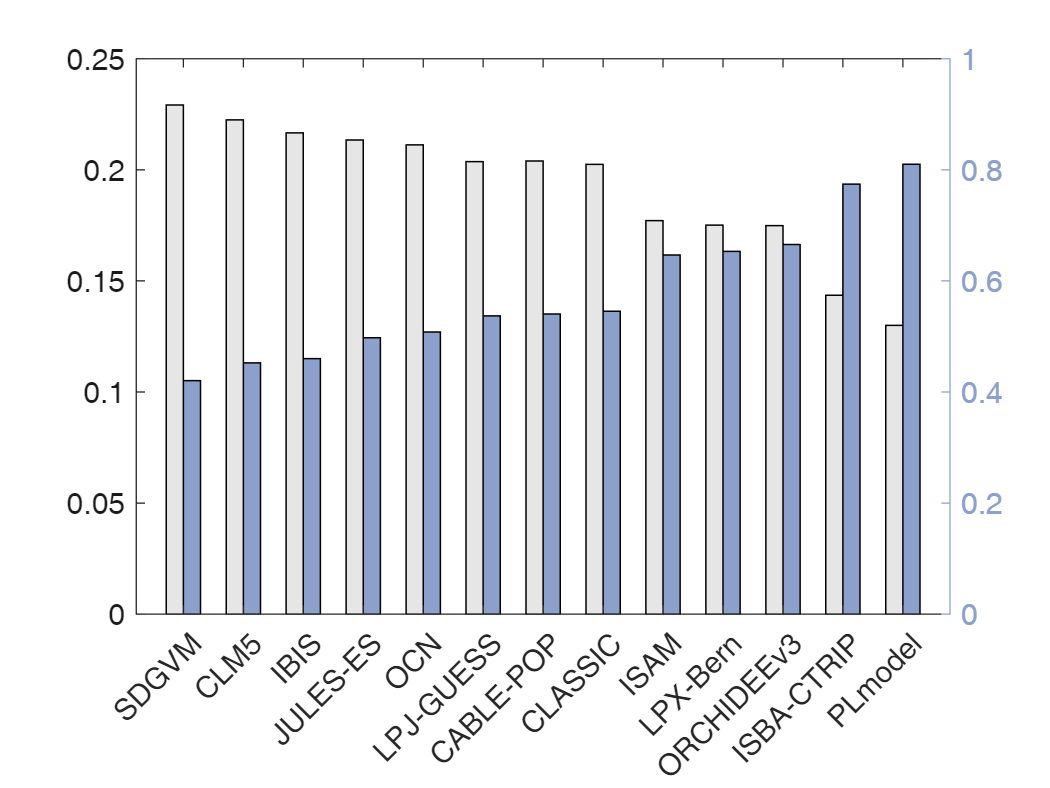

load(fullfile('../data/', ['trendy_param_output','.mat']))
load(fullfile('../data/', ['trendy_data_output','.mat']))

num = size(param_model.name,1);
% show the comparison of the trendy models
param_model.name{num+1} = 'PLmodel';
param_model.r2_fit(num+1) = 0.81;
param_model.r2_season(num+1) = 0.86;
param_model.rmse_fit(num+1) = 0.13;

[~, ind_sort] = sort(param_model.r2_fit, 1, "ascend");

X = categorical(param_model.name(ind_sort));
X = reordercats(X,param_model.name(ind_sort));


% show the map of the data
figure
colororder(cat(1, [0.1,0.1,0.1], cb_set2(3,:)))

yyaxis left
% plot(X, param_model.rmse_fit(ind_sort),"MarkerSize",12,"Marker",".","Color",cb_paired(6,:),"LineWidth",0.8);
fig_bar2 = bar(X, cat(2,param_model.rmse_fit(ind_sort),zeros(size(param_model.rmse_fit))), 'FaceColor','flat',"LineWidth",0.6,"BarWidth",1.0);
fig_bar2(1).CData(1:num,:) = repmat([0.9,0.9,0.9], [num,1]);
fig_bar2(1).CData(num+1,:) = [0.9,0.9,0.9];
% hatchfill2(fig_bar2(2),'single','HatchAngle',45);

% ylabel('RMSE')
% set(gca, 'ygrid', 'on');

yyaxis right
fig_bar = bar(X, cat(2,zeros(size(param_model.r2_fit)),param_model.r2_fit(ind_sort)),'FaceColor','flat',"LineWidth",0.6,"BarWidth",1.0);
fig_bar(2).CData(1:num,:) = repmat(cb_set2(3,:), [num,1]);
fig_bar(2).CData(num+1,:) = cb_set2(3,:);
% fig_bar.EdgeColor(num+1,:) = [0.2,0.2,0.2];
ylim([0,1])
% ylabel('R^2')
% set(gca, 'ygrid', 'on');
set(gca, 'fontsize', options.fontsize-2)

fprintf('Mean R2 = %.2f ± %.2f', mean(param_model.r2_fit(1:end-1)), std(param_model.r2_fit(1:end-1)))

Mean R2 = 0.56 ± 0.11

fprintf('Mean RMSE = %.2f ± %.2f', mean(param_model.rmse_fit(1:end-1)), std(param_model.rmse_fit(1:end-1)))

Mean RMSE = 0.20 ± 0.03

fprintf('Mean seasonality = %.2f ± %.2f', mean(param_model.r2_season(1:end-1)), std(param_model.r2_season(1:end-1)))

Mean seasonality = 0.00 ± 0.00

**Fig | Temporal trends in global greenness (*****f*****APAR****). **Global distribution of (**a**) observed and (**b**) predicted temporal trends in monthly mean *f*APAR. (**c**) Identification of the dominant driver of the trend in P-model simulated monthly mean *f*APAR, where (+) and (–) indicate positive and negative effects respectively.

Show the spatial map of the data

[fapar_obs_multi,R] = geotiffread("../data/fapar_global_modis_05d_yr.tif"); %#ok<*GTRED> 
fapar_sim_multi = geotiffread("../data/fapar_global_plmodel_05d_yr.tif");

% - The significant areas
pVal = 0.10;
% [fapar_trend_upscale, fapar_pvalue_upscale, fapar_upscale_mean] = cal_linear_trend(fapar_obs_multi, 'MK', pVal);
% [fapar_trend_sim, fapar_pvalue_sim, fapar_sim_mean] = cal_linear_trend(fapar_sim_multi, 'MK', pVal);

[fapar_trend_upscale, fapar_pvalue_upscale, fapar_upscale_mean] = cal_linear_trend(fapar_obs_multi, 'Ftest', pVal);
[fapar_trend_sim, fapar_pvalue_sim, fapar_sim_mean] = cal_linear_trend(fapar_sim_multi, 'Ftest', pVal);

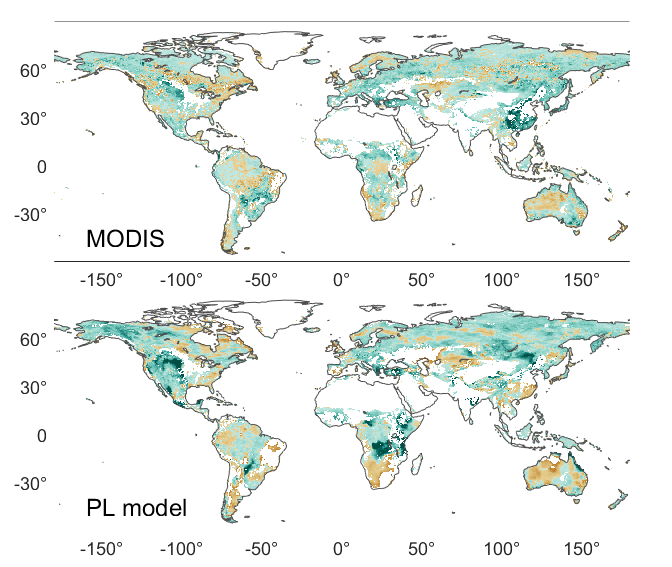

% show the spatial map
nums = 200;
options.range_trend = [-.3, .7];
CT_All = cbrewer_hint('div', 'BrBG', nums);
CT = CT_All([(nums/2*0.4+1):(nums/2*0.7), (nums/2*0.2+101):(nums/2*0.9+101)], :);

fig = figure('Color', [1 1 1]);
tiledlayout(2,1,"TileSpacing","tight","Padding","compact")
fig.Position(1) = fig.Position(1)*0.6;
fig.Position(3) = fig.Position(3)*0.8;
fig.Position(2) = fig.Position(2)*0.20;
fig.Position(4) = fig.Position(4)*0.9;

nexttile;
data_disp = fapar_trend_upscale .* 100;
data_disp(~roi_single_year) = nan;
fapar_pvalue_upscale(~roi_single_year) = nan;
geoshow_global(data_disp,'plot_pvalue','false','pvalue_matrix',fapar_pvalue_upscale,'plot_map_surface','true','plot_map_type','texturemap')
set(gca, 'Clim', options.range_trend)
text(options.text_position(1), options.text_position(2), 'MODIS','FontSize',12)

nexttile;
fapar_predicted_min_matrix_disp = fapar_trend_sim .* 100;
fapar_predicted_min_matrix_disp(~roi_single_year) = nan;
fapar_pvalue_sim(~roi_single_year) = nan;
geoshow_global(fapar_predicted_min_matrix_disp,'plot_pvalue','false','pvalue_matrix',fapar_pvalue_sim,'plot_map_surface','true','plot_map_type','texturemap');
set(gca, 'Clim', options.range_trend)
text(options.text_position(1), options.text_position(2), 'PL model','FontSize',12)

% cb = colorbar(gca,"Location","southoutside","FontSize",10); cbarrow;
% title(cb, 'g C yr^{−1}')
box on;
colormap(cat(1,[1,1,1],CT))
exportgraphics(gcf, fullfile(path_figure_output, 'fAPARtrend_pvalue.png'),"Resolution",600);

Show the attribution of factors

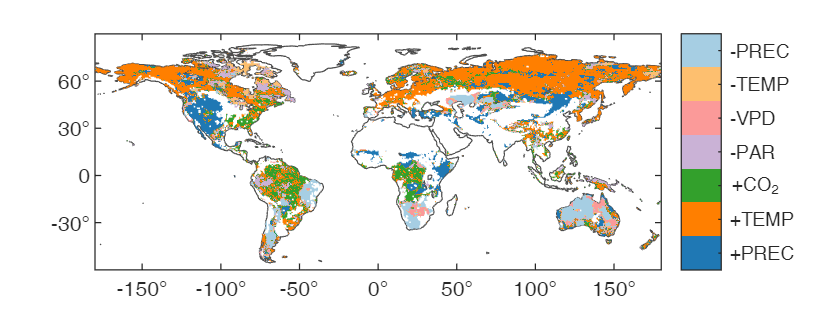

trend_green = geotiffread("../data/fapar_trend_global_plmodel_05d.tif");
trend_green_disp = trend_green;
trend_green_disp(~(abs(trend_green) > 0)) = nan;
switch 'ctrl'
    case 'diff'
        trend_green_contribute = trend_green_disp(:,:,end) - trend_green_disp;
    case 'ctrl'
        trend_green_contribute = trend_green_disp;
end

% 什么因素贡献最大？或者是正向贡献最大
[contribution_matrix, index_max] = max(abs(trend_green_contribute(:,:,1:5)), [], 3, "omitnan");
index_max(isnan(trend_green(:,:,end))) = nan;
[~, index_max_neg] = min(trend_green_contribute(:,:,1:5), [], 3, "omitnan");
[~, index_max_pos] = max(trend_green_contribute(:,:,1:5), [], 3, "omitnan");

index_max_final = index_max;

index_max_greening = index_max;
index_max_browning = index_max;

index_max_final(trend_green_contribute(:,:,end) > 0 & index_max==1) = 1; % + prec
index_max_final(trend_green_contribute(:,:,end) > 0 & index_max==3) = 2; % + PAR
index_max_final(trend_green_contribute(:,:,end) > 0 & index_max==5) = 2; % + TEMP
index_max_final(trend_green_contribute(:,:,end) > 0 & index_max==2) = 3; % + co2
index_max_final(trend_green_contribute(:,:,end) < 0 & index_max==3) = 4; % - PAR
index_max_final(trend_green_contribute(:,:,end) < 0 & index_max==4) = 5; % - VPD
index_max_final(trend_green_contribute(:,:,end) < 0 & index_max==5) = 6; % - TEMP
index_max_final(trend_green_contribute(:,:,end) < 0 & index_max==1) = 7; % - prec

fig = figure('Color', [1 1 1]);
tiledlayout(1,1,"TileSpacing","tight","Padding","compact")

fig.Position(1) = fig.Position(1)*0.6;
fig.Position(3) = fig.Position(3)*0.8;
fig.Position(2) = fig.Position(2)*0.20;
fig.Position(4) = fig.Position(4)*0.4;
        
index_max_disp = index_max_final ;
index_max_disp(~(fapar_upscale_mean>0 & roi_single_year) ) = nan;

geoshow_global(index_max_disp)
cb = colorbar;
% cb.Location = 'southoutside';
cb.Location = 'eastoutside';
% cb.Position(4) = cb.Position(4)*0.6;

tickNames = {'+PREC', '+TEMP', '+CO_2', '-PAR', '-VPD', '-TEMP', '-PREC'};
nums = length(tickNames);
% CT = cbrewer('div', 'Spectral', nums);
% CT = cbrewer('qual', 'Set2', nums);
cb_paired = cbrewer_hint('qual', 'Paired', 12);

% Can we find some better colours for the third plot. Try to relate the
% colours for the variables, e.g. pale blue for –ve precip, dark blue for
% +precip, light red for –temp, dark red for +ve temp. I’ve put some
% possible colours here, but this might need a bit of experimenting
CT_disp = cb_paired([2, 8, 4, 9, 5, 7, 1],:);
% CT_disp = cb_paired([1, 7, 3, 10, 6, 8, 2],:); % reverse
% colormap(CT(nums/2:end,:))
set(gca, 'clim', [0.5, nums+0.5])
% clim([0.5, nums+0.5])
color_list = [[0 0.4470 0.7410]; ... % blue
    [0.4660 0.6740 0.1880]; ... % green
    [0.9290 0.6940 0.1250]; ... % yellow
    [189,190,192]./256;... % grey [0.3000 0.3000 0.3000]; ... % grey
    [0.4940 0.1840 0.5560]; ... % purple

    [0.8500 0.3250 0.0980]; ... % orange
    cb_paired(1,:); ... % light blue

    % [0.6350 0.0780 0.1840]; ... % dark red
    ];
% set(gca, 'ylim',[-60,90])
colormap(CT_disp(1:end, :))
% colormap(color_list)
% colorbar
cb.Ticks = 1:nums;
cb.TickLabels = tickNames;
axis([-180 180 -60 90])
% grid on
box on

**Fig | Temporal trends in gross primary production (GPP, PgC yr****−1****). **Predicted inter-annual changes and temporal trends in global GPP from the PL and TRENDY models. Solid lines represent annual values; dashed line indicate the linear regression trend. The uncertainty envelope is the standard deviation of the global GPP simulated by the TRENDY models. The counter-factual PL model experiment (*A*0) assumes no change in greenness over the past two decades, and thus isolates the contribution of *A*0 to increasing GPP.

Years = YearBgn:YearEnd;

fig = figure;
fig.Position(3) = fig.Position(3)*0.8;
fig.Position(4) = fig.Position(4)*0.7;

cb_paired = [0.6510    0.8078    0.8902
    0.1216    0.4706    0.7059
    0.6980    0.8745    0.5412
    0.2000    0.6275    0.1725
    0.9843    0.6039    0.6000
    0.8902    0.1020    0.1098
    0.9922    0.7490    0.4353
    0.9990    0.4980         0
    0.7922    0.6980    0.8392
    0.4157    0.2392    0.6039
    0.9990    0.9990    0.6000
    0.6941    0.3490    0.1569];

nexttile;

%Make red line non-transparent
% save(fullfile(dir_volume, '科研数据\TRENDY\output\trendy_v9\', var_name, 'tif', ['trendy_param_output_', var_name, '.mat']), 'param_model', '-mat');
% save(fullfile(dir_volume, '科研数据\TRENDY\output\trendy_v9\', var_name, 'tif', ['trendy_data_output_', var_name, '.mat']), 'data_model', '-mat');

load(fullfile('../data/', ['trendy_param_output_', 'gpp', '.mat']));
load(fullfile('../data/', ['trendy_data_output_', 'gpp', '.mat']));
load(fullfile('../data/', ['gpp_global_pgc', '.mat']));
hold on

% options.method_gpp = 'pmodel vs. PL model';
options.method_gpp = 'trendy vs. PL model';
if strcmpi(options.method_gpp, 'trendy vs. PL model')
    % Not including DLEM,VISIT
    fig_shaded = shadedErrorBar(data_model.year(1,:), data_model.lai([1,2,4:13],:), {@mean,@std}, 'lineprops', {'LineStyle','-','LineWidth',2.4,'Color',[76,77,79]/255},'transparent',false,'patchSaturation',0.075);
    % fig_shaded = shadedErrorBar(data_model.year(1,:), data_model.lai(:,:), {@mean,@std}, 'lineprops', {'LineStyle','-','LineWidth',2.4,'Color',[76,77,79]/255},'transparent',false,'patchSaturation',0.075);
    fig(3) = fig_shaded.mainLine;

    line_color = cb_paired(2,:);
    % [stats1, b1, fig(1)] = timeSeriesPlotwithBreakYear(gpp_pg_fluxcom_annual, 2001:2019, 1900, "pointColor",line_color,"fitlineColor",line_color,"StatisDisp","off","StatisDispItem","slope","StatisLocation","northeast","lineColor",line_color,"linewidth",2.4, "logicRegLine","false");
    line_color = [0.4,0.4,0.4];
    [stats_obs, b_obs, fig(1), linear_model_obs] = timeSeriesPlotwithBreakYear(mean(data_model.lai([1,2,4:13],:),1), Years(2:end), 1900, "pointColor",line_color,"fitlineColor",line_color,"StatisDisp","off","StatisDispItem","slope","StatisLocation","northeast","lineColor",line_color,"linewidth",2.4, "logicRegLine","true","markersize",18,"fitlinewidth",1.4,"fitlinestyle","--");
    line_color = cb_paired(6,:);
    [stats_sim, b_sim, fig(2), linear_model_sim] = timeSeriesPlotwithBreakYear(trend_series_vector_sim(2:end), Years(2:end), 1900, "pointColor",line_color,"fitlineColor",line_color,"StatisDisp","off","StatisDispItem","slope","StatisLocation","northeast","lineColor",line_color,"linewidth",2.4, "logicRegLine","true","logicScatter","true","fitlinewidth",1.4,"fitlinestyle","--");
    line_color = cb_paired(2,:);
    [stats_ctr, b_ctr, fig(3), linear_model_ctr] = timeSeriesPlotwithBreakYear(trend_series_vector_sim_bgn(2:end), Years(2:end), 1900, "pointColor",line_color,"fitlineColor",line_color,"StatisDisp","off","StatisDispItem","slope","StatisLocation","northeast","lineColor",line_color,"linewidth",2.4, "logicRegLine","true","logicScatter","true","markersize",18,"fitlinewidth",1.4,"fitlinestyle","--");

    % add legend of the data
    legend(fig, {['TRENDY', ': ', num2str(b_obs(2),'%.2f'),' PgC yr^{−2}'], ['PL model: ', num2str(b_sim(2),'%.2f'),' PgC yr^{−2}'], ['\it{A}\rm_{0}: ', num2str(b_ctr(2),'%.2f'),' PgC yr^{−2}']},"Box","off","Location", 'northwest',"FontSize",10);
elseif strcmpi(options.method_gpp, 'pmodel vs. PL model')
    [stats_obs, b_obs, fig(1), linear_model_obs] = timeSeriesPlotwithBreakYear(trend_series_vector_obs(2:end), Years(2:end), 1900, "pointColor",cb_pastel2(1,:),"lineColor",cb_set2(1,:),"fitlineColor",cb_set2(1,:),"StatisDisp","off","StatisDispItem","slope","StatisLocation","northeast","linewidth",2.4,"logicRegLine","true","markersize",18,"fitlinewidth",1.4,"fitlinestyle","--");
    line_color = cb_paired(2,:);
    [stats_ctr, b_ctr, fig(3), linear_model_sim] = timeSeriesPlotwithBreakYear(trend_series_vector_sim_bgn(2:end), Years(2:end), 1900, "pointColor",line_color,"fitlineColor",line_color,"StatisDisp","off","StatisDispItem","slope","StatisLocation","northeast","lineColor",line_color,"linewidth",2.4, "logicRegLine","true","logicScatter","false","fitlinewidth",1.4,"fitlinestyle","--");
    [stats_sim, b_sim, fig(2), linear_model_ctr] = timeSeriesPlotwithBreakYear(trend_series_vector_sim(2:end), Years(2:end), 1900, "pointColor",cb_paired(3,:),"lineColor",cb_paired(4,:),"fitlineColor",cb_paired(4,:),"StatisDisp","off","StatisDispItem","slope","StatisLocation","northeast","linewidth",2.4,"logicRegLine","true","markersize",18,"fitlinewidth",1.4,"fitlinestyle","--");

    % add legend of the data
    % legend(fig, {['Pmodel ', 'Trend = ', num2str(b2(2),'%.2f')], ['PL model Trend = ', num2str(b3(2),'%.2f')]},"Box","off","Location", 'northwest',"FontSize",10);
    legend(fig, {['Pmodel ', 'Trend = ', num2str(b_obs(2),'%.2f')], ['PL model Trend = ', num2str(b_sim(2),'%.2f')], ['PL model Control = ', num2str(b_ctr(2),'%.2f')]},"Box","off","Location", 'northwest',"FontSize",10);
    legend("Position", [0.15,0.66,0.43,0.25])
end

% show the trend in GPP
% legend(fig, {['Upscaled Flux', '= ', num2str(b1(2),'%.2f')], ['Trendy ', 'Trend = ', num2str(b2(2),'%.2f')], ['PL model Trend = ', num2str(b3(2),'%.2f')], ['PL model Control = ', num2str(b4(2),'%.2f')]},"Box","off","Location", 'northwest',"FontSize",10);
[r,pvalue] = corr(trend_series_vector_sim, trend_series_vector_obs);
str=['\it{r}\rm = ',sprintf('%.2f',r), '', pvalue_star_convert(pvalue), ''];

hold off
% grid on

box on;
%修饰一下
ax=gca;hold(ax,'on');
ax.YLim=[115,145];
% ax.LineWidth=1.2;
ax.Box='on';
ax.TickDir='in';
ax.XMinorTick='on';
ax.YMinorTick='on';
ax.ZMinorTick='on';
ax.XColor=[.3,.3,.3];
ax.YColor=[.3,.3,.3];
ax.ZColor=[.3,.3,.3];
% ax.FontWeight='bold';
% ax.FontName='Cambria';
ax.FontSize=10;
ax.GridLineStyle='--';

xl = xlim;
yl = ylim;
switch 'southeast'
    case 'northwest'
        x_position = (xl(2) - xl(1))*0.06 + xl(1);
        y_position = (yl(2) - yl(1))*0.90 + yl(1);
    case 'northeast'
        x_position = (xl(2) - xl(1))*0.80 + xl(1);
        y_position = (yl(2) - yl(1))*0.92 + yl(1);
    case 'southwest'
        x_position = (xl(2) - xl(1))*0.06 + xl(1);
        y_position = (yl(2) - yl(1))*0.1 + yl(1);
    case 'southeast'
        x_position = (xl(2) - xl(1))*0.60 + xl(1);
        y_position = (yl(2) - yl(1))*0.1 + yl(1);
    otherwise
        x_position = (xl(2) - xl(1))*0.06 + xl(1);
        y_position = (yl(2) - yl(1))*0.9 + yl(1);
end

% text(x_position, y_position, str, 'FontSize', 10, 'Color', 'k')

% ylim([0.3, 0.45])
hold off
xlabel('Year')
ylabel('Global GPP (PgC yr^{−1})')
num_years = 19;
disp(['MODIS ', 'Trend = ', num2str(b_obs(2)*num_years,'%.2f'), '(', num2str(b_sim(2)*num_years,'%.2f'), ') ± ', num2str(linear_model_obs.Coefficients.SE(2)*num_years,'%.3f'), '(', num2str(linear_model_sim.Coefficients.SE(2)*num_years,'%.3f'),')'])

MODIS Trend = 8.79(11.29) ± 0.713(1.248)


disp(['Simulated ', 'Trend = ', num2str(b_sim(2)*num_years,'%.2f'), '(', num2str(b_ctr(2)*num_years,'%.2f'), ') ± ', num2str(linear_model_sim.Coefficients.SE(2)*num_years,'%.3f'), '(', num2str(linear_model_ctr.Coefficients.SE(2)*num_years,'%.3f'),')'])

Simulated Trend = 11.29(7.93) ± 1.248(0.619)


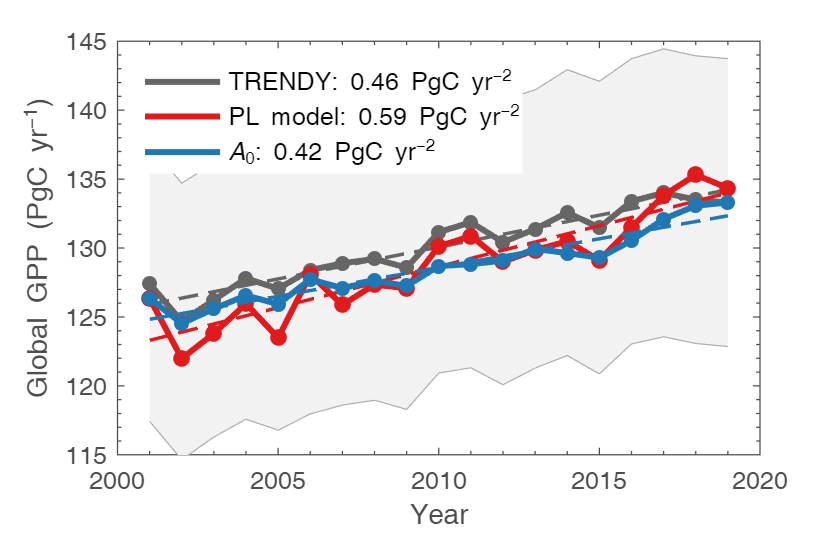

exportgraphics(gcf, fullfile(path_figure_output, 'GPPtrend_series.png'),"Resolution",600);